## Solution to Question 2

Transfer function for the system:

s = tf('s') ; % need s to represent a transfer function for the step response
sys = 1 / ( (3*s^2) + 20 ) 


sys =
 
      1
  ----------
  3 s^2 + 20
 
Continuous-time transfer function.



Apply step input and get analytical solution using ilaplace():

syms S % using capital letter instead for symbolic s which is required for ilaplace
step_sys = 1 / ( (3*S^3) + 20*S ) 

$$step\_sys = \frac{1}{3\,S^{3}+20\,S}$$

step_sys_TD = ilaplace(step_sys) 

$$step\_sys\_TD = \frac{1}{20}-\frac{\cos\left(\frac{2\,\sqrt{3}\,\sqrt{5}\,t}{3}\right)}{20}$$

Plot the analytical solution against MATLAB's built-in step response function: 

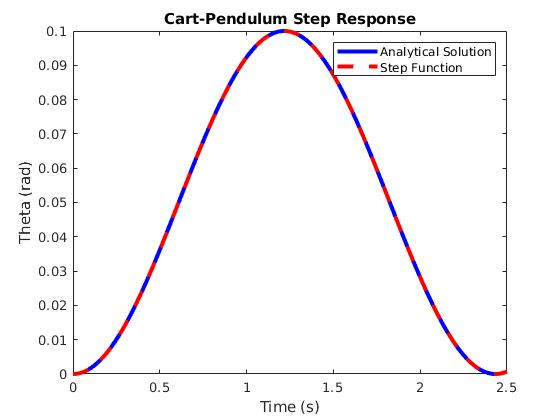

syms t
time = (0:0.01:2.5)' ; 
step_sys_TD_array = subs(step_sys_TD,t,time) ; % analytical solution
[Yt, ts] = step(sys,time) ; % matlab solution

% plot
figure(1)
plot(time,step_sys_TD_array,'-b','LineWidth',3)
hold on
plot(ts,Yt,'--r','LineWidth',3)
legend('Analytical Solution','Step Function')
xlabel('Time (s)') ; ylabel('Theta (rad)') ; title('Cart-Pendulum Step Response') ; 